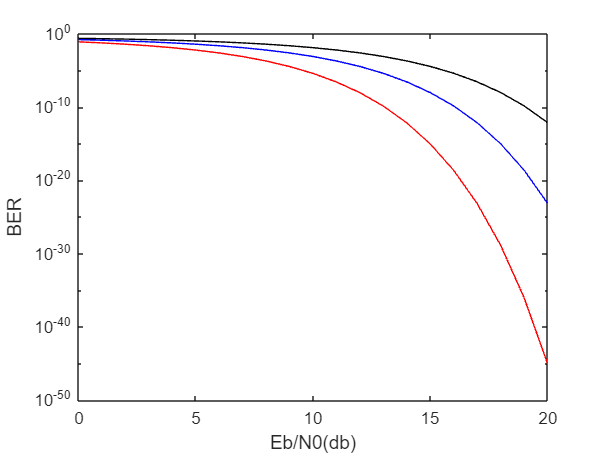

clc;
close all;
EbN0dB = 0:20;
EbN0 = 10.^(EbN0dB/10);
pe_bpsk = 0.5 * erfc(sqrt(EbN0));
pe_bfsk = 0.5 * erfc(sqrt(EbN0/2));
pe_bask = 0.5 * erfc(sqrt(EbN0/4));

semilogy(EbN0dB, pe_bpsk, 'r', EbN0dB, pe_bfsk, 'b', EbN0dB, pe_bask, 'k');
xlabel('Eb/N0(db)');
ylabel('BER');